% Clear command window, workspace variables, and close all figures
clear; clc; close all;

% Set the path to the folder containing the layer data
layerfolder = 'data/Capas_Colombia_30S/';

% Read in the layer data from the specified folder
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 40.562642 seconds.



% Generate initial point for niche generation using a virtual species method
InfoInitialPoint = InitialPoint(Dimensions,'coeff');

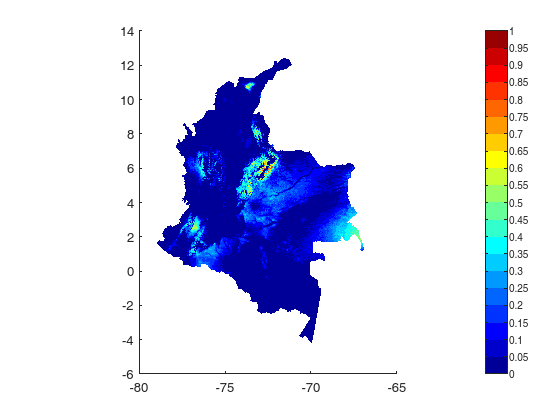

% Generate the niche map using niche generation algorithm with the initial point
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

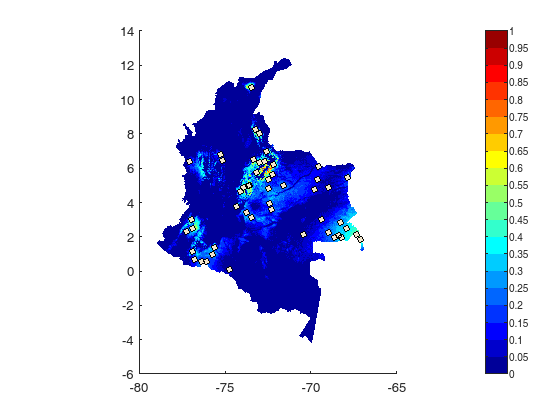

% Sample virtual species using the generated niche map
T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -1, true, 'GenSP', true, true);

% Close all figures
close all, clf

% Show graphics
show=true;

% Remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier=false;

% Remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true; 

%ColoringBorder generates classifier object with atributes nodes = environmental variables for each frontier point, 
% T = table with samples and information
% readInfo = dimensions of the map
% alpha = shrinking factor

classA1 = ColoringBorder(T,Dimensions,1,false,outlier,outlier2); 

MapMetric(MapInfo.Map,classA1.map,false)

ans =     0.6346    0.7149


%T = table with samples and information
%readInfo = dimensions of the map
%percentile = percentile with which the radius will be taken
%alpha = shrinking factor

classB1 = ColoringRadius(T,Dimensions,1,25,show,outlier,outlier2); 

classB2 = ColoringRadiusPercentile(T,Dimensions,1,25,true,false,false); 

MapMetric(MapInfo.Map,classA1.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.7666    0.8283


MapMetric(MapInfo.Map,classB1.map,false) 

ans =     0.8907    0.9275


MapMetric(MapInfo.Map,classB2.map,false)

ans =     0.9111    0.9047


classA2 = ColoringWeightedBorder(T,Dimensions,1,show,outlier,outlier2);


[F,t] = ecdf(classA1.radius);
plot(t,1-F)
xlabel('X'); ylabel('F(x)')
title('Niche Probability Intensity Based on distance')